## Traveling Salesperson Problem with QUBO

The classic Traveling Salesperson Problem (TSP) involves a group of cities (locations) that a salesperson must visit before returning to the start location. The problem is to minimize the total distance the salesperson travels. This topic shows how to convert a TSP to a Quadratic Unconstrained Binary Optimization (QUBO) problem, and to solve the QUBO problem using the tabu search algorithm.

**Problem Data**

The data for a TSP consists of city locations and the distances between each pair of cities. The distances can be given as a matrix `D`, where `D(i,j)` is the distance from city `i` to city `j`. This example uses the Pythagorean rule to calculate distances, assuming a flat earth. The solution depends only on the distances, not the city locations. But to plot the solution, you need the locations.

Specify the following pseudorandom city locations:

N = 9; % Number of cities
rng default % For reproducibility
stopsLon = 1.5*rand(N,1);
stopsLat = rand(N,1);
plot(stopsLon,stopsLat,"ko")

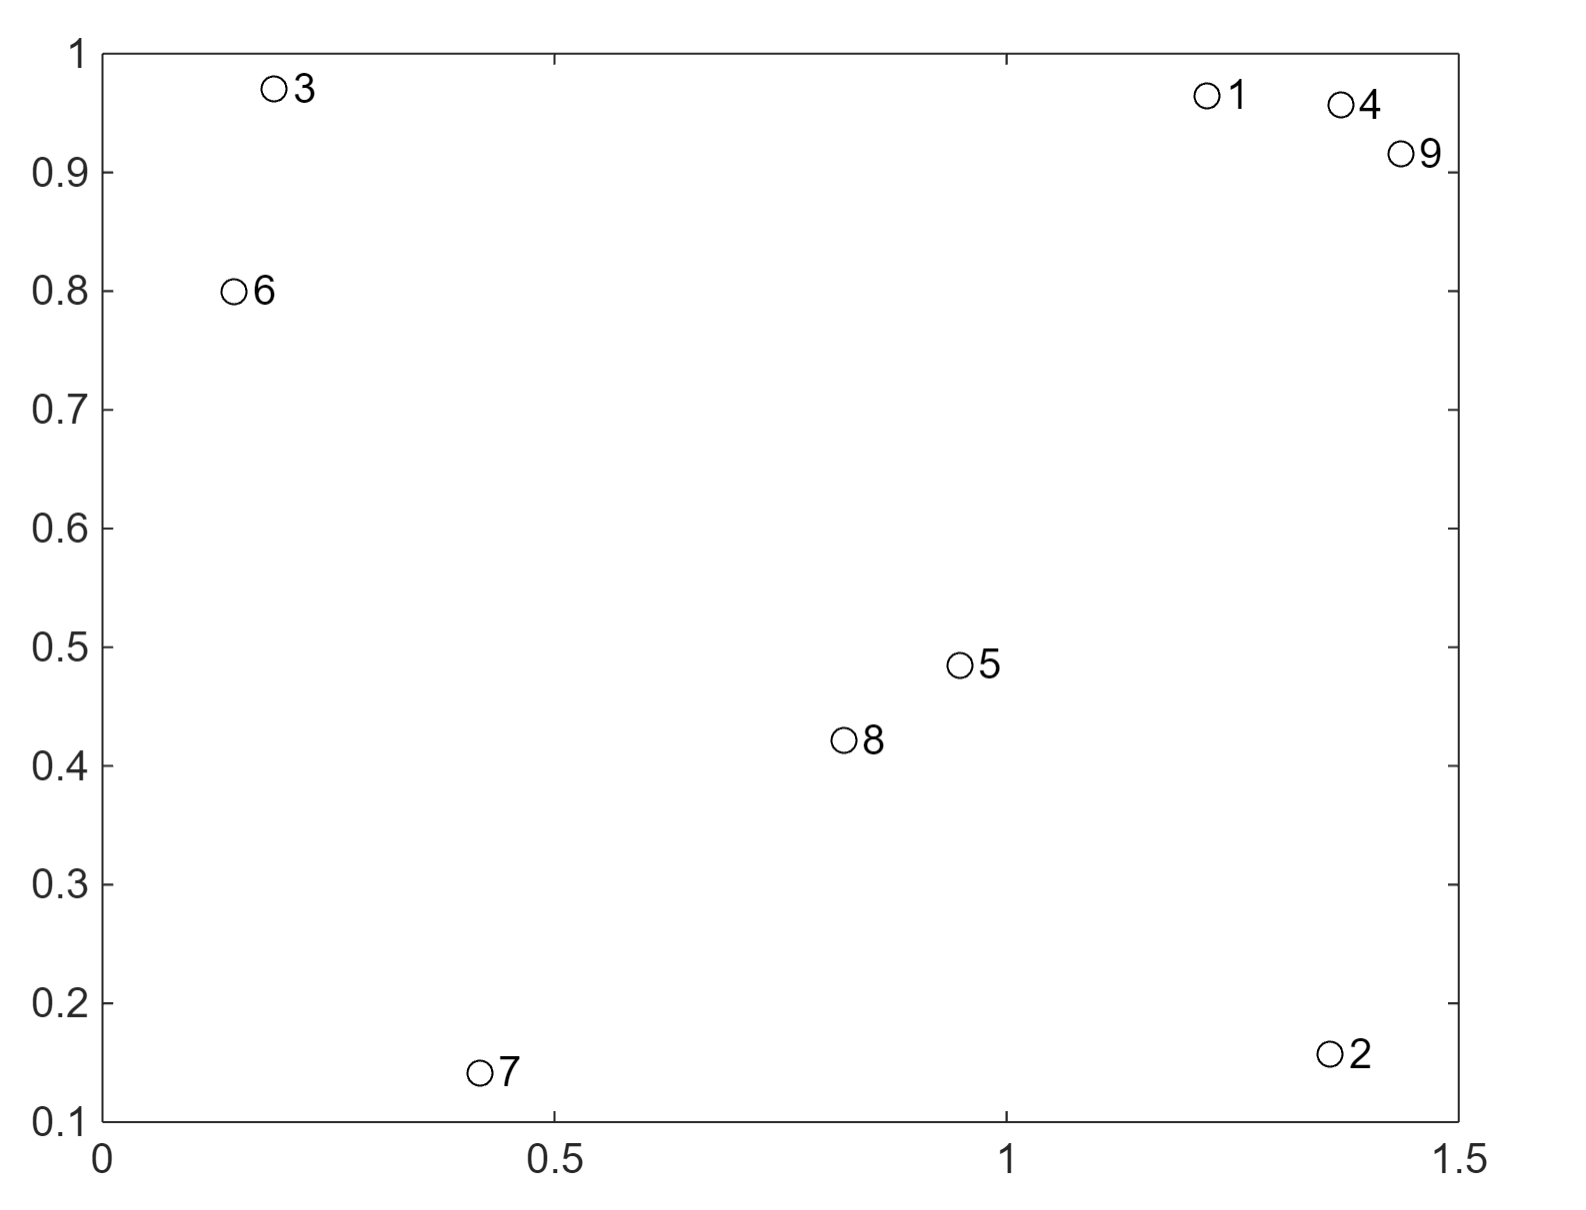

Calculate the distances between the cities using the `hypot` function.

[X,Y] = meshgrid(1:N);
dist = hypot(stopsLon(X) - stopsLon(Y),stopsLat(X) - stopsLat(Y));

**Convert to QUBO: Theory**

For $N$ cities, use $N^2$ binary variables *x*(*i*,*j*), where *i* represents the index of a city and *j* represents the order of the city in the route. In other words, if city *i* is visited at step *j* of the route, then *x*(*i*,*j*) = 1.

According to Lucas [[2]](https://it.mathworks.com/help/matlab/math/quantum-tsp.html#mw_2fdb273e-b3a8-4c26-92e7-2d56ad7ba3bb), the following equations suffice to specify that the *x*(*i*,*j*) variables represent a route.

$\sum^{N}_{i = 1} (1-\sum_{j = 1}^N x(i,j))^2
$ = 0 

$\sum^{N}_{j = 1} (1-\sum_{i = 1}^N x(i,j))^2
$  = 0

These equations ensure that each city is visited only once, and each step of the route is in one city.

If some cities are not reachable directly from other cities, also include the equation


$$\sum_{\text{No path from i to j}} \sum_{k = 1}^N x(i,k)x(j,k+1) = 0$$


This equation ensures that when no direct path exists from *i* to *j*, then at any time *k* when the route visits *i*, the route does not visit *j* at time *k* + 1.

To convert the TSP to a QUBO problem, use the following objective function, which is scaled by a positive number *M*. Each expression in the objective function is a penalty for the solution failing to satisfy one of the previous equations.


$$f(x) = M \sum_{i=1}^N (1-\sum_{j=1}^N x(i,j))^2 + M \sum_{j=1}^N (1-\sum_{i=1}^N x(i,j))^2 + M\sum_{\text{No path from i to j}} \sum_{k = 1}^N x(i,k)x(j,k+1) 
$$


As you can see, *f*(*x*) = 0 when *x* represents a valid route. All of the expressions in *f*(*x*) are in QUBO form.

To finish the conversion from TSP to QUBO, include the cost of the route in the objective function. Let *D*(*i*,*j*) be the distance of a direct path from *i* to *j*. The objective function for the TSP is


$$f(x) + \sum_{uv} D(u,v) \sum_{j = 1}^N x(u,j) x(v, j+1)$$


Here, interpret *x*(*v*,*N*+1) as *x*(*v*,1), meaning the route returns to the start location at step *N*+1.

Suppose that the multiplier *M* satisfies 0 < max(*D*) < *M*. When you specify *M* this large, the minimal objective function takes place where *f*(*x*) = 0. In this case, the constraints are satisfied, so the *x* variables represent a valid route.

The final step in converting the quadratic expressions for distance and penalty to a QUBO problem is to represent them in matrix form. To do that, we use the following helper function:

function QP = tsp2qubo(dist)
%   QP = TSP2QUBO(DIST) returns a QUBO problem from the traveling salesperson
%   problem specified by the distance matrix DIST. DIST is an N-by-N
%   nonnegative matrix where DIST(i,j) is the distance between locations
%   i and j.

% Copyright 2023 The MathWorks, Inc.

N = size(dist,1);
% Create constraints on routes
A = eye(N);
B = ones(N);
Q0 = kron(A,B);
Q1 = kron(B,A);
% Create upper diagonal matrices of distances
v = ones(N-1,1);
A2 = diag(v,1);
Q2 = kron(B,A2); % Q2 has a diagonal just above the main diagonal in each block
C = kron(dist,B);
Q2 = Q2.*C; % Q2 has an upper diagonal dist(i,j)
% Create dist(j,i) in the upper-right corner of each block
E = zeros(N);
E(1,N) = 1;
Q3 = kron(B,E); % Q3 has a 1 in the upper-right corner of each block
CP = kron(dist',B); % dist' for D(j,i)
Q3 = Q3.*CP; % Q3 has dist(j,i) in the upper-right corner of each block
% Add the multipliers
M = max(max(dist));
QN = sparse(M*(Q0 + Q1)*N^2 + Q2 + Q3);
% Symmetrize
QN = (QN + QN.')/2;

% Include the constant and linear terms
c = -4*ones(N^2,1)*M*N^2;
d = 2*N*M*N^2;

QP = qubo(QN,c,d);

end

## **Solve TSP Using **`solve`

Earlier, you created the distance matrix `dist`. Convert the distance matrix to a TSP using the `tsp2qubo` helper function, and then solve the problem.

Q = tsp2qubo(dist);
result = solve(Q);

Plot the city locations and the calculated route.

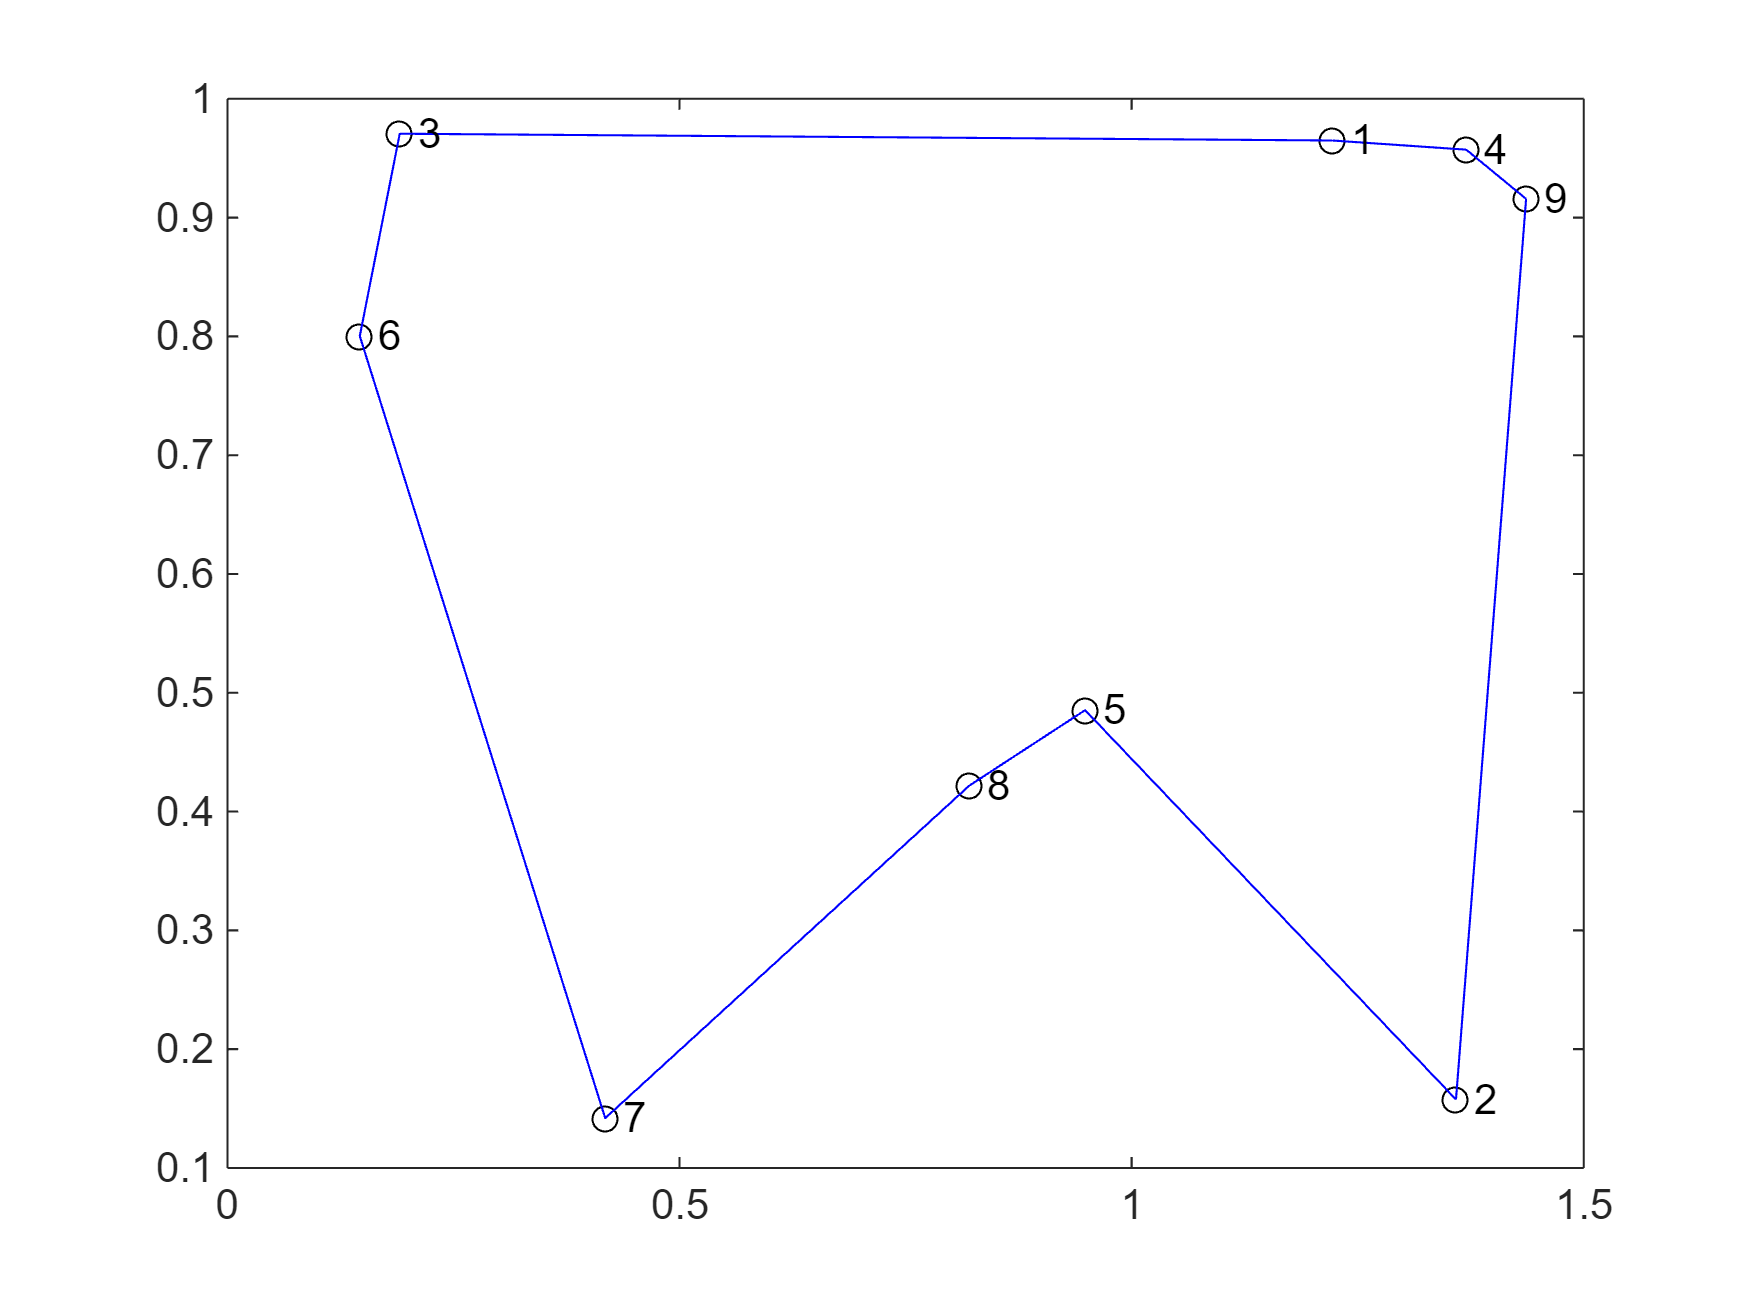

binx = result.BestX;
binx = reshape(binx,N,[]);
ordr = zeros(1,N);
for i = 1:N
    ordr(i) = find(binx(i,:)); % Find order of cities in route
end

hold on
plot(stopsLon(ordr),stopsLat(ordr),"ko")
plot(stopsLon(ordr),stopsLat(ordr),"b-")
plot(stopsLon(ordr([N 1])),stopsLat(ordr([N,1])),"b-")
for i = 1:length(stopsLon)
text(stopsLon(i)+0.02,stopsLat(i),num2str(i))
end
hold off

disp(ordr)

     2     5     8     7     6     3     1     4     9



Find the distance of the route by adding the length of each leg.

myd = 0;
for i = 1:(N-1)
    myd = myd + dist(ordr(i),ordr(i+1));
end
myd = myd + dist(ordr(N),ordr(1))

myd = 4.0665

Find the distance by evaluating the objective function at the solution.

evaluateObjective(Q,result.BestX)

ans = 4.0665